data_filename = './sample_data/vectornav_vertical_5_17.csv';

% Our sample data has headers on the first line, so skip it
data = csvread(data_filename, 1);

% We'll use the time that the sample starts as each time
time = data(:, 1) * 10^(-9);
time = time - time(1);

% Using the first timestamp, calculate the sampling rate.
% With the configuration for the VectorNav, this will remain consistent.
sampling_rate = 1 / (time(2) - time(1));
target_frequency = 10;

time_downsampled = downsample(time, int32(sampling_rate) / target_frequency);

accel = data(:, 10:12);
gyro = data(:, 7:9);
mag = data(:, 19:21);

ahrs_sensor_data = table;
ahrs_sensor_data.Accelerometer = accel;
ahrs_sensor_data.Gyroscope = gyro;
ahrs_sensor_data.Magnetometer = mag;

[ahrs_acceleration, ahrs_velocity, ahrs_position] = filter_derived_heave(ahrs_sensor_data, sampling_rate, target_frequency);

imu_sensor_data = table;
imu_sensor_data.Accelerometer = accel;
imu_sensor_data.Gyroscope = gyro;

[imu_acceleration, imu_velocity, imu_position] = filter_derived_heave(imu_sensor_data, sampling_rate, target_frequency);

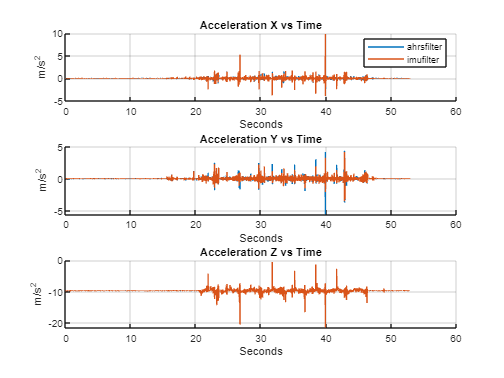

clf;

subplot(3,1,1);
hold on;
plot(time, ahrs_acceleration(:, 1));
plot(time, imu_acceleration(:, 1));
title("Acceleration X vs Time")
xlabel("Seconds")
ylabel("m/s^2")
legend("ahrsfilter", "imufilter");
hold off;
grid on;

subplot(3,1,2);
hold on;
plot(time, ahrs_acceleration(:, 2));
plot(time, imu_acceleration(:, 2));
title("Acceleration Y vs Time")
xlabel("Seconds")
ylabel("m/s^2")
hold off;
grid on;

subplot(3,1,3);
hold on;
plot(time, ahrs_acceleration(:, 3));
plot(time, imu_acceleration(:, 3));
title("Acceleration Z vs Time")
xlabel("Seconds")
ylabel("m/s^2")
hold off;
grid on;

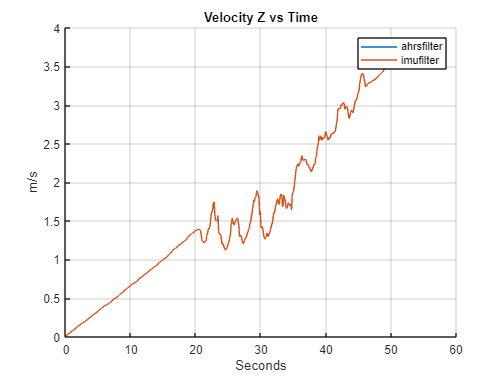

clf;
hold on;
plot(time_downsampled, ahrs_velocity);
plot(time_downsampled, imu_velocity);
ylabel("m/s");
xlabel("Seconds")
title("Velocity Z vs Time");
legend("ahrsfilter", "imufilter")
grid on;
hold off;

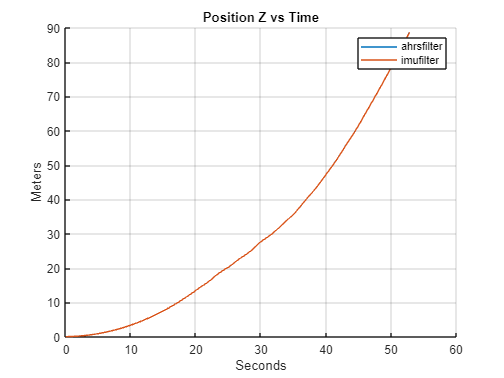

clf;
hold on;
plot(time_downsampled, ahrs_position);
plot(time_downsampled, imu_position);
ylabel("Meters");
xlabel("Seconds")
title("Position Z vs Time");
legend("ahrsfilter", "imufilter")
grid on;
hold off;